
clc
clear

data_dam = load('./data/AL0625_1_dam.mat');
data_undam = load('./data/AL0625_1_undam.mat');
addpath(genpath( './all_libs/WIMF'))
rng(42);

## Preprocess data and mask to have the required shape for further steps

% Wave data with damage present
wave_data_dam_ = data_dam.AL0625_1_dam;
wave_data_dam = reshape(wave_data_dam_,sqrt(size(wave_data_dam_,1)),sqrt(size(wave_data_dam_,1)),size(wave_data_dam_,2));

% wave_data_dam = wave_data_dam(:,:,1:100);

% Wave data without damage

wave_data_undam_ = data_undam.AL0625_1_undam;
wave_data_undam = reshape(wave_data_undam_,sqrt(size(wave_data_undam_,1)),sqrt(size(wave_data_undam_,1)),size(wave_data_undam_,2));

% wave_data_undam = wave_data_undam(:,:,1:100);


% Estimate Primary source and damage location using energy method
wave_power = sum(wave_data_dam.^2,3);

mx = max(wave_power(:));
[trueI,trueJ] = find(wave_power==mx);

mg = min(wave_power(:));
[trueI_,trueJ_] = find(wave_power==mg);


% Data used for processing

wave_data_dam = wave_data_dam(:,:,1:100);
wave_data_undam = wave_data_undam(:,:,1:100);


lx = linspace(0,99,size(wave_data_undam,1));
ly = linspace(0,99,size(wave_data_undam,2));

## Computation of Eigenvalues and Eigenvectors of Second Derivative Matrix to use for reconstruction

Lx = 4*del2(eye(size(wave_data_dam,2)));
Ly = 4*del2(eye(size(wave_data_dam,1)));
Lt = 4*del2(eye(size(wave_data_dam,3)));

[V_x,Dx] = eig(Lx);
[V_y,Dy] = eig(Ly);
[V_t,Dt] = eig(Lt);



## Primary Source Localization


A = wave_data_dam(:,:,5);

centers = zeros(4,2,6);

A1B1 = floor([0.15,0.20;0.06,0.20;0.10,0.10;0.06,0.06;0.04,0.04;0.02,0.02]*100);
A3B3 = floor([0.83,0.85;0.90,0.90;0.90,0.90;0.94,0.94;0.96,0.96;0.98,0.98]*100);

for i = 1:6
    a1 = A1B1(i,1);
    b1 = A1B1(i,2);
    a3 = A3B3(i,1);
    b3 = A3B3(i,2);
    
    a2 = a1;
    b2 = b3;
    b4 = b1;
    a4 = a3;

    centers(1,1,i) = a1; centers(1,2,i) = b1;
    centers(2,1,i) = a2; centers(2,2,i) = b2;
    centers(3,1,i) = a3; centers(3,2,i) = b3;
    centers(4,1,i) = a4; centers(4,2,i) = b4;
end

% Assuming 'centers' is a 4x2x6 array and 'A' is a 100x100 matrix
% centers(i,:,indx) contains [x,y] coordinates of the i-th vertex for rectangle indx
% VERTICES ARE IN CLOCKWISE ORDER

% Load all results files
all_files = dir('./results/*_results.mat');

% Filter out secondary_results.mat
result_files = [];
for i = 1:length(all_files)
    [~, name, ~] = fileparts(all_files(i).name);
    if ~strcmp(name, 'secondary_results')
        result_files = [result_files; all_files(i)];
    end
end

% Define different marker shapes and colors for each file
marker_styles = {'o', '*', 's', 'd', '^', 'v', 'p', 'h', '+', 'x', '<', '>'};
marker_colors = lines(length(marker_styles));  % Generate distinct colors

% Initialize a cell array to store positions from each file separately
file_positions = cell(length(result_files), 6);
file_names = cell(length(result_files), 1);

% Load positions from all result files
for file_idx = 1:length(result_files)
    file_path = fullfile(result_files(file_idx).folder, result_files(file_idx).name);
    loaded_data = load(file_path);

    % Store the filename (without path and extension) for legend
    [~, name, ~] = fileparts(result_files(file_idx).name);

    % Custom naming for WIRL files
    if strcmp(name, 'WIRL_results')
        file_names{file_idx} = 'WIRL-full';
    elseif startsWith(name, 'primary_') && endsWith(name, '_results')
        % Extract the number between 'primary_' and '_results'
        % e.g., 'primary_1_results' -> 'WIRL-1'
        parts = split(name, '_');
        if length(parts) >= 2
            num_str = parts{2};
            file_names{file_idx} = ['WIRL-' num_str];
        else
            % Fallback if parsing fails
            file_names{file_idx} = strrep(name, '_', ' ');
        end
    else
        % Remove everything after the last underscore for other files
        last_underscore = find(name == '_', 1, 'last');
        if ~isempty(last_underscore)
            name = name(1:last_underscore-1);
        end
        file_names{file_idx} = strrep(name, '_', '-');  % Replace remaining underscores with spaces
    end

    % Check if 'Positions' exists in the loaded data
    if isfield(loaded_data, 'Positions')
        positions = loaded_data.Positions;

        % Store positions from this file
        for indx = 1:6
            if ~isempty(positions{indx})
                file_positions{file_idx, indx} = positions{indx};
            end
        end
    end
end

% Create figure with 2x3 subplot layout
figure('Position', [100, 100, 1400, 900]);

% Define colors for rectangles and background (matching reference image)
rect_color = [0.53, 0.66, 0.87];    % Soft blue for inside rectangle
bg_color = [0.82, 0.9, 0.68];      % Pale greenish yellow for outside region
rect_alpha = 0.85;                   % Higher opacity for rectangle
bg_alpha = 0.85;                     % Higher opacity for background region
matrix_alpha = 0.15;                  % Lower transparency for matrix A overlay

% Define subplot labels
labels = {'(a)', '(b)', '(c)', '(d)', '(e)', '(f)'};

% Variables to store legend info (will be created only for first subplot)
legend_handles = [];
legend_labels = {};

% Loop through each rectangle
for indx = 1:6
    % Create subplot
    subplot(2, 3, indx);
    hold on;

    % Extract individual vertices for current rectangle
    a1 = centers(1,1,indx); b1 = centers(1,2,indx);
    a2 = centers(2,1,indx); b2 = centers(2,2,indx);
    a3 = centers(3,1,indx); b3 = centers(3,2,indx);
    a4 = centers(4,1,indx); b4 = centers(4,2,indx);

    % Rectangle vertices (clockwise, closing the polygon)
    rect_x = [a1, a2, a3, a4, a1];
    rect_y = [b1, b2, b3, b4, b1];

    % Fill the entire square with background color FIRST
    fill([0, 100, 100, 0], [0, 0, 100, 100], ...
         bg_color, 'FaceAlpha', bg_alpha, 'EdgeColor', 'none');

    % Fill the rectangle on top
    fill(rect_x, rect_y, rect_color, 'FaceAlpha', rect_alpha, ...
         'EdgeColor', 'none');

    % Display background matrix A with transparency ON TOP
    h = imagesc([0 100], [0 100], A);
    set(h, 'AlphaData', matrix_alpha);  % Make matrix A transparent
    colormap(gca, 'parula');  % Using parula colormap as requested

    axis equal;
    axis([0 100 0 100]);
    set(gca, 'YDir', 'normal');

    % Plot positions from each file with different markers
    for file_idx = 1:length(result_files)
        if ~isempty(file_positions{file_idx, indx})
            pos = file_positions{file_idx, indx};

            % Get marker style (cycle through if more files than markers)
            marker_idx = mod(file_idx - 1, length(marker_styles)) + 1;

            % Plot with unique marker and color
            h_plot = plot(pos(:,2), pos(:,1), ...
                marker_styles{marker_idx}, ...
                'Color', marker_colors(file_idx, :), ...
                'MarkerSize', 4, ...
                'LineWidth', 1.5, ...
                'MarkerFaceColor', marker_colors(file_idx, :));

            % Store handle and label for legend (only for first subplot)
            if indx == 1
                legend_handles = [legend_handles, h_plot];
                % if file_idx<8
                legend_labels = [legend_labels, file_names{file_idx}];
                % else
                % 
                % end
            end
        end
    end

    % Add legend only for the first subplot
    if indx == 1 && ~isempty(legend_handles)
        lgd = legend(legend_handles, legend_labels, ...
            'Location', 'best', ...
            'FontSize', 4);
    end

    % Add labels and formatting
    xlabel('Plate width [mm]', 'FontSize', 11);
    ylabel('Plate length [mm]', 'FontSize', 11);
    title(sprintf('Mask %s', labels{indx}), 'FontSize', 11);

    % Make tick labels smaller
    set(gca, 'FontSize', 9);

    % Match the grid style from reference
    grid on;
    set(gca, 'GridAlpha', 0.15);  % Subtle grid
    box on;

    hold off;
end


% Adjust subplot spacing
set(gcf, 'Color', 'w');





% % Load the .mat files
% load('./results/primary_secondary_results.mat', 'Positions');
% load('./results/secondary_results.mat', 'Positions_defect');
% 
% 
% % Define mask labels
% mask_labels = {'(a)', '(b)', '(c)', '(d)', '(e)', '(f)'};
% 
% % Initialize cell arrays to store table data
% nCases = 6; % Number of cases
% 
% % Preallocate cell arrays for the tables
% primaryTableData = cell(nCases, 1);
% defectTableData = cell(nCases, 1);
% 
% % Process Positions_primary data
% for i = 1:nCases
%     positions = Positions{i};
%     if ~isempty(positions)
%         % Format as coordinate pairs: (x1, y1), (x2, y2), ...
%         coordStrings = cell(size(positions, 1), 1);
%         for j = 1:size(positions, 1)
%             coordStrings{j} = sprintf('(%.2f, %.2f)', lx(positions(j, 1)), ly(positions(j, 2)));
%         end
%         primaryTableData{i} = strjoin(coordStrings, '; ');
%     else
%         primaryTableData{i} = 'No detections';
%     end
% end
% 
% % Process Positions_defect data
% for i = 1:nCases
%     positions = Positions_defect{i};
%     if ~isempty(positions)
%         % Format as coordinate pairs
%         coordStrings = cell(size(positions, 1), 1);
%         for j = 1:size(positions, 1)
%             coordStrings{j} = sprintf('(%.2f, %.2f)', lx(positions(j, 1)), ly(positions(j, 2)));
%         end
%         defectTableData{i} = strjoin(coordStrings, '; ');
%     else
%         defectTableData{i} = 'No detections';
%     end
% end
% 
% % Create the tables using mask labels
% % Table 1: Primary damage positions
% primaryTable = table(mask_labels', primaryTableData, ...
%     'VariableNames', {'Mask', 'Estimated_Primary_Source_Locations'});
% 
% % Table 2: Secondary defect positions
% defectTable = table(mask_labels', defectTableData, ...
%     'VariableNames', {'Mask', 'Locations_Secondary_Source_Locations'});
% 
% % Display the tables
% disp('Table 1: Primary Source Detection Results for WIMF (N_D = 4)');
% disp(primaryTable);
% 
% fprintf('\n\n');
% 
% disp('Table 2: Defect Detection Results for WIRL (N_D = 1)');
% disp(defectTable);
% 
% % Optional: Save tables to file
% writetable(primaryTable, './results/primary_damage_table.csv');
% writetable(defectTable, './results/secondary_defect_table.csv');
% 
% fprintf('\nTables saved to CSV files.\n');




% Load all result files
all_files = dir('./results/*_results.mat');

% Files to exclude
exclude_files = {'WIRL_results.mat', 'secondary_results.mat'};

% Filter out excluded files
valid_files = {};
for i = 1:length(all_files)
    if ~ismember(all_files(i).name, exclude_files)
        valid_files{end+1} = all_files(i).name;
    end
end

% Number of valid files determines grid layout
n_files = length(valid_files);
m = ceil(n_files / 2);  % columns for 2-row grid

% Specify index (1 to 6)
indx = 3;  % Change this as needed
time_slice = 10;
% Create figure
figure('Position', [100, 100, 300*m, 550]);

for i = 1:n_files
    filename = valid_files{i};
    filepath = fullfile('./results', filename);
    data = load(filepath);
    
    if strcmp(filename, 'WIMF_recon_results.mat')
        recon = inv_spectral_wave_transform(data.all_Ds{indx} * data.all_xs{indx}, V_x, V_y, V_t);
    else
        recon = data.all_recons{indx};
    end
    
    subplot(2, m, i);
    imagesc(recon(:,:,time_slice));
    axis xy;
    axis square;
    colorbar;
    xlabel('Plate Width [mm]');
    ylabel('Plate Length [mm]');
    
    % Clean up title
    [~, name, ~] = fileparts(filename);
    name = strrep(name, '_results', '');
    name = strrep(name, 'WIMF_recon', 'WIRL');
    title(strrep(name, '_', '-'), 'FontSize', 9);
end

colormap('parula');
sgtitle(sprintf('Reconstructions: index = %d, slice %d', indx, time_slice), 'FontSize', 12);

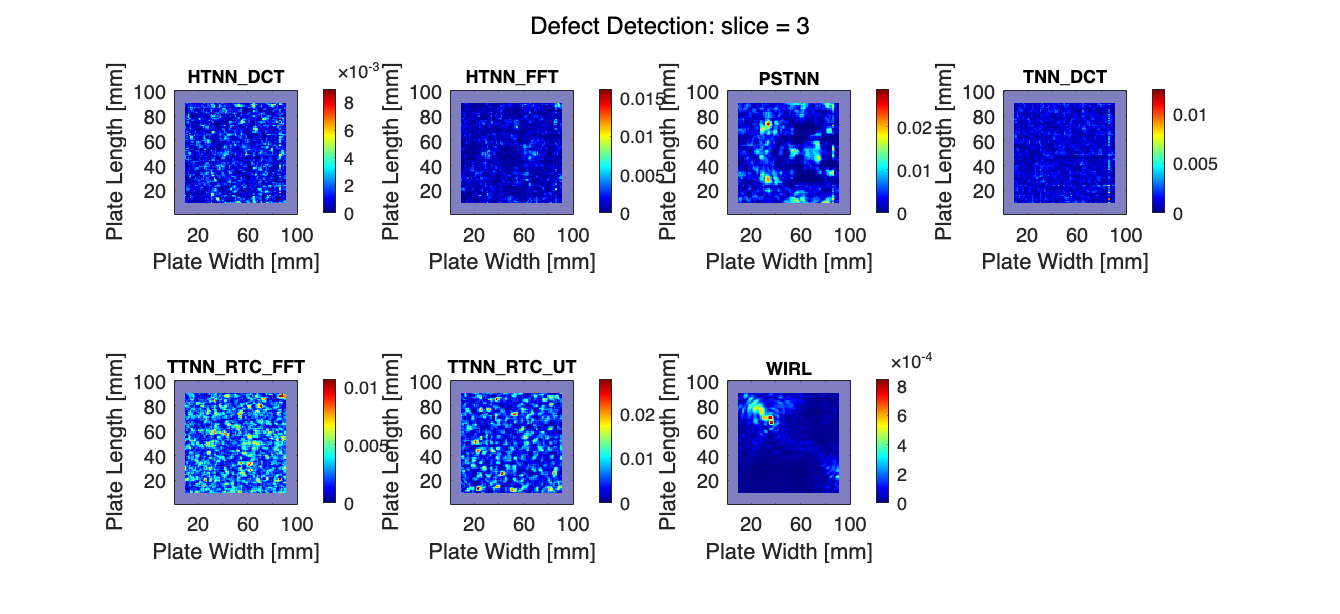

% Load all defect files
all_files = dir('./results/*_defect.mat');


% Mask Calc

A1B1 = floor([0.15,0.20;0.06,0.20;0.10,0.10;0.06,0.06;0.04,0.04;0.02,0.02]*100);
A3B3 = floor([0.83,0.85;0.90,0.90;0.90,0.90;0.94,0.94;0.96,0.96;0.98,0.98]*100);

for i = 1:6
    a1 = A1B1(i,1);
    b1 = A1B1(i,2);
    a3 = A3B3(i,1);
    b3 = A3B3(i,2);
    
    a2 = a1;
    b2 = b3;
    b4 = b1;
    a4 = a3;

    centers(1,1,i) = a1; centers(1,2,i) = b1;
    centers(2,1,i) = a2; centers(2,2,i) = b2;
    centers(3,1,i) = a3; centers(3,2,i) = b3;
    centers(4,1,i) = a4; centers(4,2,i) = b4;
end

% Slice index for 3D arrays
slice = 3;

unmask = ones(size(wave_data_dam,1),size(wave_data_dam,2));

a1 = centers(1,1,slice);
a4 = centers(4,1,slice);
b1 = centers(1,2,slice);
b2 = centers(2,2,slice);


unmask(a1:a4,b1:b2,:) = 0;

% Number of files determines grid layout
n_files = length(all_files);
m = ceil(n_files / 2);

% Overlay color (e.g., white)
overlay_color = [1, 1, 1];  % RGB: white
overlay_alpha = 0.5;  % transparency (0 = invisible, 1 = opaque)

% Create figure
figure('Position', [100, 100, 300*m, 550]);

for i = 1:n_files
    filename = all_files(i).name;
    filepath = fullfile('./results', filename);
    data = load(filepath);
    
    % Get the data
    disp_data = data.disp_wave_power_est;
    
    % Check dimensions
    if ndims(disp_data) == 2
        plot_data = disp_data;
    else
        plot_data = disp_data(:,:,slice);
    end
    
    subplot(2, m, i);
    imagesc(plot_data);
    axis xy;
    axis square;
    hold on;
    
    % Create RGB overlay
    overlay = cat(3, overlay_color(1)*ones(size(unmask)), ...
                     overlay_color(2)*ones(size(unmask)), ...
                     overlay_color(3)*ones(size(unmask)));
    h = image(overlay);
    set(h, 'AlphaData', overlay_alpha * unmask);  % transparent where unmask = 0
    
    hold off;
    colorbar;
    colormap('jet');
    xlabel('Plate Width [mm]');
    ylabel('Plate Length [mm]');
    
    % Clean up title
    [~, name, ~] = fileparts(filename);
    name = strrep(name, '_defect', '');
    title(strrep(name, '_', '\_'), 'FontSize', 9);
end

sgtitle(sprintf('Defect Detection: slice = %d', slice), 'FontSize', 12);


% Load all *_results.mat files from results/ subdirectory and display positions table
% Excludes WIMF_recon_results.mat

%% Find and load result files
resultsDir = 'results';
filePattern = fullfile(resultsDir, '*_results.mat');
matFiles = dir(filePattern);

% Exclude WIMF_recon_results.mat
excludeFile = 'WIMF_recon_results.mat';
matFiles = matFiles(~strcmp({matFiles.name}, excludeFile));

if isempty(matFiles)
    error('No *_results.mat files found in %s (excluding %s)', resultsDir, excludeFile);
end

%% Process each file and build table data
rowNames = {};
positionData = {};

for i = 1:length(matFiles)
    % Extract algorithm name from filename (remove _results.mat suffix)
    filename = matFiles(i).name;
    algorithmName = strrep(filename, '_results.mat', '');
    
    % Load the file
    filepath = fullfile(resultsDir, filename);
    data = load(filepath, 'Positions');
    
    if ~isfield(data, 'Positions')
        warning('File %s does not contain "Positions" variable. Skipping.', filename);
        continue;
    end
    
    Positions = data.Positions;  % 1x6 cell array
    
    % Determine n from the first non-empty cell element
    n = 0;
    for k = 1:6
        if ~isempty(Positions{k})
            n = size(Positions{k}, 1);  % number of positions
            break;
        end
    end
    
    if n == 0
        warning('File %s has empty Positions. Skipping.', filename);
        continue;
    end
    
    % Generate row names and extract position data
    if n == 1
        % Single position: just use algorithm name
        rowNames{end+1} = algorithmName;
        rowData = cell(1, 6);
        for k = 1:6
            if ~isempty(Positions{k})
                rowData{k} = Positions{k}(1, :);
            else
                rowData{k} = NaN;
            end
        end
        positionData{end+1} = rowData;
    else
        % Multiple positions: j=1 to n-1 get "-j", j=n gets "-full"
        for j = 1:n
            if j < n
                rowNames{end+1} = sprintf('%s-%d', algorithmName, j);
            else
                rowNames{end+1} = sprintf('%s-full', algorithmName);
            end
            
            rowData = cell(1, 6);
            for k = 1:6
                if ~isempty(Positions{k}) && size(Positions{k}, 1) >= j
                    rowData{k} = Positions{k}(j, :);
                else
                    rowData{k} = NaN;
                end
            end
            positionData{end+1} = rowData;
        end
    end
end

%% Build and display the table
numRows = length(rowNames);
columnLabels = {'(a)', '(b)', '(c)', '(d)', '(e)', '(f)'};

% Convert position data to displayable format
tableData = cell(numRows, 6);
for r = 1:numRows
    for c = 1:6
        pos = positionData{r}{c};
        if isnumeric(pos) && all(isnan(pos))
            tableData{r, c} = 'N/A';
        elseif isnumeric(pos)
            % Format position as string (e.g., "[x, y]" or "[x, y, z]")
            tableData{r, c} = sprintf('[%s,%s]', string(lx(pos(1))),string(lx(pos(2))));
        else
            tableData{r, c} = 'N/A';
        end
    end
end

% Create and display table
T = cell2table(tableData, 'VariableNames', columnLabels, 'RowNames', rowNames);
disp('Primary Source Positions by Algorithm and Mask:');

Primary Source Positions by Algorithm and Mask:


disp(' ');

disp(T);

                        (a)            (b)            (c)            (d)            (e)            (f)    
                    ___________    ___________    ___________    ___________    ___________    ___________

    HALRTC          {'[59,20]'}    {'[90,65]'}    {'[90,65]'}    {'[80,6]' }    {'[4,32]' }    {'[96,31]'}
    HTNN_DCT        {'[50,67]'}    {'[51,67]'}    {'[50,67]'}    {'[50,68]'}    {'[35,32]'}    {'[35,31]'}
    HTNN_FFT        {'[50,67]'}    {'[49,67]'}    {'[49,67]'}    {'[84,77]'}    {'[83,76]'}    {'[84,82]'}
    PSTNN           {'[50,67]'}    {'[50,67]'}    {'[49,67]'}    {'[49,72]'}    {'[42,56]'}    {'[70,11]'}
    TNN_DCT         {'[50,67]'}    {'[51,67]'}    {'[50,67]'}    {'[


% Load all *_results.mat files from results/ subdirectory and display position error table
% Computes norm of difference between estimated and true position [trueI, trueJ]
% Excludes WIMF_recon_results.mat


truePosition = [lx(trueI), ly(trueJ)];

%% Find and load result files
resultsDir = 'results';
filePattern = fullfile(resultsDir, '*_results.mat');
matFiles = dir(filePattern);

% Exclude WIMF_recon_results.mat
excludeFile = 'WIMF_recon_results.mat';
matFiles = matFiles(~strcmp({matFiles.name}, excludeFile));

if isempty(matFiles)
    error('No *_results.mat files found in %s (excluding %s)', resultsDir, excludeFile);
end

%% Process each file and build table data
rowNames = {};
errorData = [];

for i = 1:length(matFiles)
    % Extract algorithm name from filename (remove _results.mat suffix)
    filename = matFiles(i).name;
    algorithmName = strrep(filename, '_results.mat', '');
    
    % Load the file
    filepath = fullfile(resultsDir, filename);
    data = load(filepath, 'Positions');
    
    if ~isfield(data, 'Positions')
        warning('File %s does not contain "Positions" variable. Skipping.', filename);
        continue;
    end
    
    Positions = data.Positions;  % 1x6 cell array
    
    % Determine n from the first non-empty cell element
    n = 0;
    for k = 1:6
        if ~isempty(Positions{k})
            n = size(Positions{k}, 1);  % number of positions
            break;
        end
    end
    
    if n == 0
        warning('File %s has empty Positions. Skipping.', filename);
        continue;
    end
    
    % Generate row names and compute error norms
    if n == 1
        % Single position: just use algorithm name
        rowNames{end+1} = algorithmName;
        rowErrors = zeros(1, 6);
        for k = 1:6
            if ~isempty(Positions{k})
                estimatedPos = Positions{k}(1, 1:2);  % Take first two elements [I, J]
                estimatedPos = [lx(estimatedPos(1)),ly(estimatedPos(2))];
                rowErrors(k) = norm(estimatedPos - truePosition);
            else
                rowErrors(k) = NaN;
            end
        end
        errorData = [errorData; rowErrors];
    else
        % Multiple positions: j=1 to n-1 get "-j", j=n gets "-full"
        for j = 1:n
            if j < n
                rowNames{end+1} = sprintf('%s-%d', algorithmName, j);
            else
                rowNames{end+1} = sprintf('%s-full', algorithmName);
            end
            
            rowErrors = zeros(1, 6);
            for k = 1:6
                if ~isempty(Positions{k}) && size(Positions{k}, 1) >= j
                    estimatedPos = Positions{k}(j, 1:2);  % Take first two elements [I, J]
                    estimatedPos = [lx(estimatedPos(1)),ly(estimatedPos(2))];
                
                    rowErrors(k) = norm(estimatedPos - truePosition);
                else
                    rowErrors(k) = NaN;
                end
            end
            errorData = [errorData; rowErrors];
        end
    end
end

%% Build and display the table
columnLabels = {'(a)', '(b)', '(c)', '(d)', '(e)', '(f)'};

% Create and display table
T = array2table(errorData, 'VariableNames', columnLabels, 'RowNames', rowNames);
disp('Position Error Norms (distance from true position):');

Position Error Norms (distance from true position):


disp(sprintf('True Position: [%g, %g]', lx(trueI), ly(trueJ)));

True Position: [49, 66]


disp(' ');

disp(T);

                     (a)       (b)       (c)       (d)       (e)       (f)  
                    ______    ______    ______    ______    ______    ______

    HALRTC          47.074    41.012    41.012    67.535      56.4      58.6
    HTNN_DCT        1.4142    2.2361    1.4142    2.2361     36.77    37.696
    HTNN_FFT        1.4142         1         1    36.688     35.44    38.484
    PSTNN           1.4142    1.4142         1         6    12.207    58.873
    TNN_DCT         1.4142    2.2361    1.4142    19.799     36.77    37.696
    TTNN_RTC_FFT    1.4142    1.4142    12.042    42.521    36.401    37.577
    TTNN_RTC_UT     30.017    47.202    54.489     11.18    